# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 11-Oct-2024 10:22:34

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["t1", "x", "y", "vx", "vy"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("C:\Users\papas\Downloads\Perros.csv", opts);

## Convert to output type

t1 = tbl.t1;
x = tbl.x;
y = tbl.y;
vx = tbl.vx;
vy = tbl.vy;

## Clear temporary variables

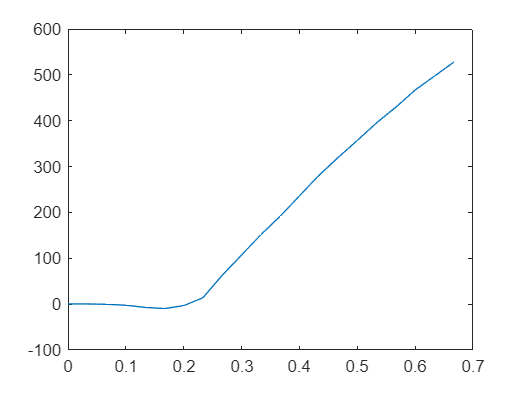

clear opts tbl
plot(t1,x)

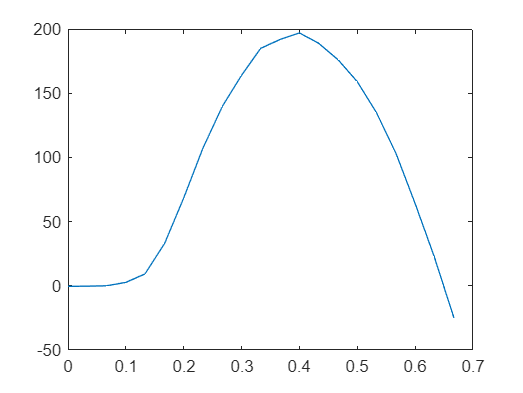

plot(t1,y)

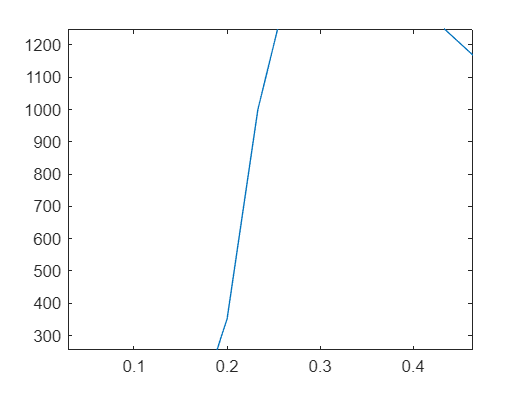

plot(t1,vx)

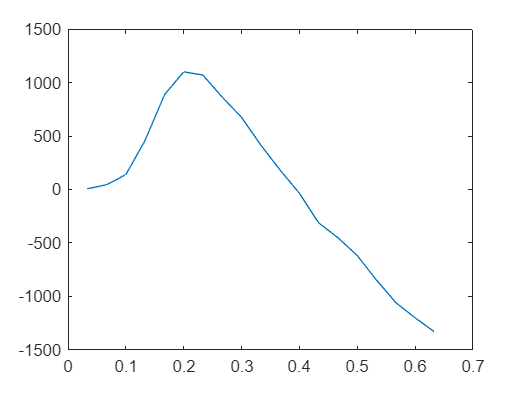

plot(t1,vy)

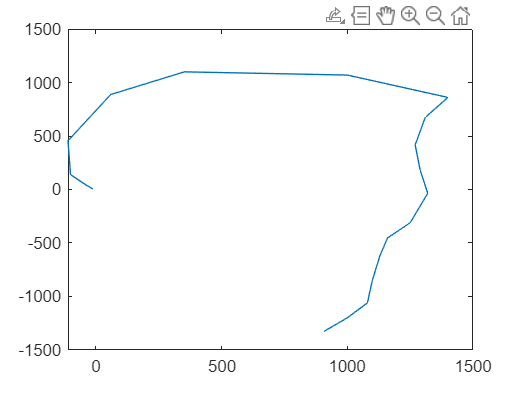

plot(vx,vy)

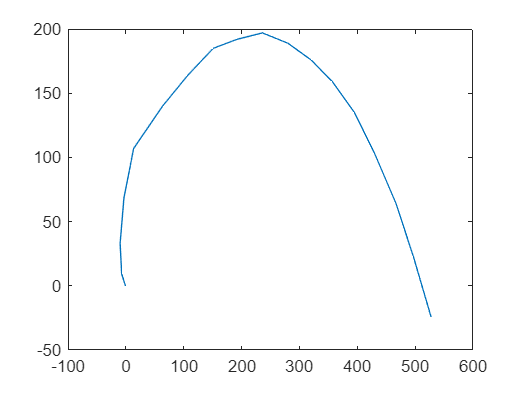

plot(x,y)